Nearest Neighbour Interpolation Based Image Zoom  : Sai Siddartha Maram 101603293

%Read Image and give required zoom 
image=imread('me.png');
zoom=1

zoom = 1

Now extract dimenstions rows,coloumns and channel using size

[r c d] = size(image);

floor() : rounds the number to the nearest integer less than it

find the new dimenstions of the image after zoom, that would be original dimensions times the required zoom

rn = floor(zoom*r);
cn = floor(zoom*c);

create blank image with new dimensions let it be im_zoom

s = zoom;
im_zoom = zeros(rn,cn,d);

iterate through each row, for each element in the row divide it by the zoom (s) and make sure its datatype in uint, this is why we use cast

%% nearest neighbour
for i = 1:rn;
x = i/s;
near_i = cast(round(x),'uint16');
if near_i == 0
near_i = 1;
end

Do the same thru coloumns

for j = 1:cn;
y = j/s;
near_j = cast(round(y),'uint16');
if near_j == 0
near_j = 1;
end

Now once you have the location of each element in the image array in the new zoomed image place them in 

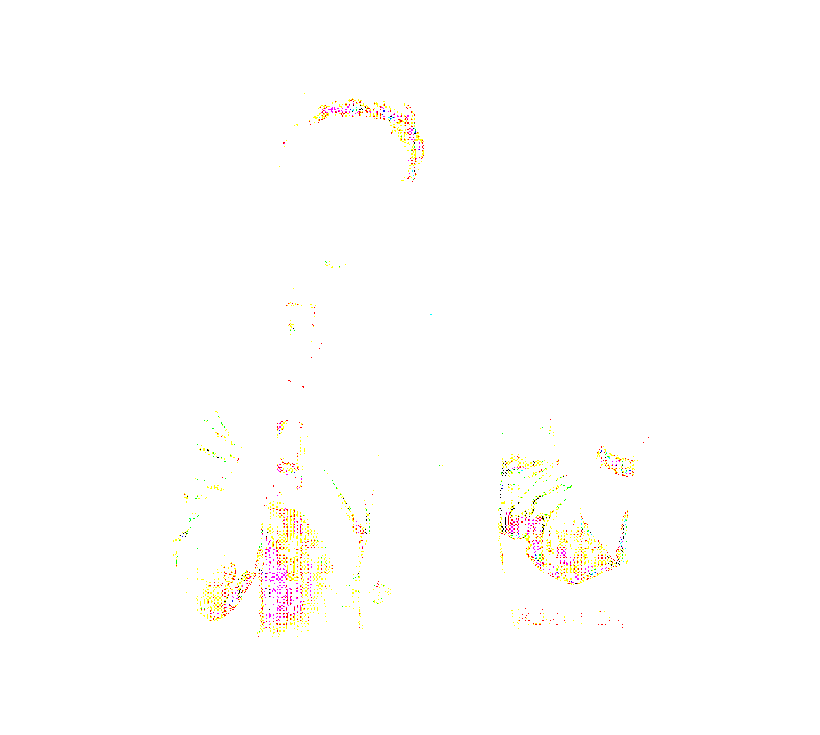

im_zoom(i,j,:) = image(near_i,near_j,:);
end
end
imzoom = im_zoom;
imshow(imzoom);